# ---- ESTABLISHING COMMUNICATION ----

port = "COM10";      
baud = 115200;
outfile = "samples.csv";

% ---- OPEN SERIAL ----
s = serialport(port, baud);
configureTerminator(s, "LF");

disp("Waiting for START...");

Waiting for START...


data = [];
recording = false;

while true
    line = readline(s);
    line = strtrim(line);
    if line == "START"
        disp("Recording started");
        recording = true;
        continue
    end
    if line == "END"
        disp("Recording ended");
        break
    end
    if recording
        val = str2double(line);
        if ~isnan(val)
            data(end+1) = val;
        end
    end
end

Recording started


Recording ended



% ---- SAVE TO CSV ----
writematrix(data', outfile);
disp("Saved to samples.csv");

Saved to samples.csv


## ---- READING AND HANDLING THE SIGNAL ----

signal = readmatrix("samples.csv");
fs = 8000;       % Sampling frequency
audio = signal;

%% Time Axis
t = (0:length(audio)-1) / fs;

%% FFT Parameters
Nfft = 4096;
window = hann(Nfft);

%% Select Short Frame (quasi-stationary)
frame = audio(1:Nfft) .* window;

%% FFT
X = fft(frame, Nfft);
X = abs(X(1:Nfft/2+1));   % One-sided magnitude
f = (0:Nfft/2) * fs / Nfft;

%% Normalize Spectrum
X = X / max(X);
X_db = 20*log10(X + eps);

%% ---- Band-pass for 300-3400 Hz ----
f_low = 300;
f_high = 3400;

% Indices within desired frequency band
band_idx = (f >= f_low) & (f <= f_high);

% Filter frequency and spectrum
f_band = f(band_idx);
X_db_band = X_db(band_idx);

%% Peak Detection within band
[pks, locs_idx] = findpeaks(X_db_band, f_band, ...
    "MinPeakHeight", -40, ...
    "MinPeakDistance", 40);

## ---- PLOTS ----

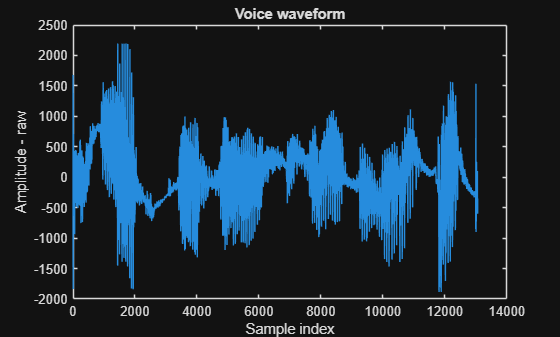

figure

% Raw data
plot(data);
xlabel("Sample index");
ylabel("Amplitude - raw");
title("Voice waveform");

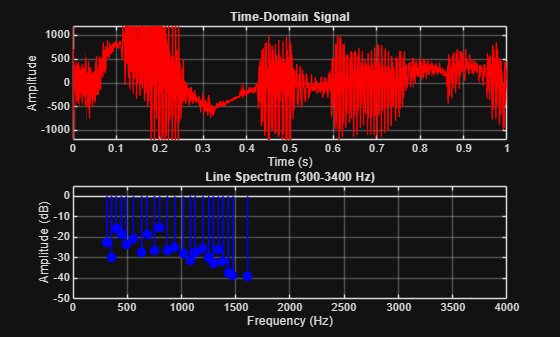


% Time-domain signal
subplot(2,1,1)
plot(t, audio, 'r', 'LineWidth', 1)
grid on
xlabel("Time (s)")
ylabel("Amplitude")
title("Time-Domain Signal")
xlim([0 1])
ylim([-1200 1200])

% Line spectrum (300-3400 Hz)
subplot(2,1,2)
stem(locs_idx, pks, 'b', 'filled', 'LineWidth', 1.2)
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
title("Line Spectrum (300-3400 Hz)")
ylim([-50 5])
xlim([0 4000])

## ---- FEATURE EXTRACTION ----

% ---- Select analysis frame ----
frameLen = 2048;
frame = audio(1:frameLen);
frame = frame - mean(frame);         % DC removal
frame = frame .* hann(frameLen);     % Windowing

%% 1. Fundamental Frequency (F0)
r = xcorr(frame);
r = r(frameLen:end);                 % positive lags only

minLag = floor(fs/400);              % 400 Hz
maxLag = floor(fs/50);               % 50 Hz

[~, idx] = max(r(minLag:maxLag));
lag = idx + minLag - 1;
f0 = fs / lag;

%% FFT for spectral features
Nfft = 4096;
X = fft(frame, Nfft);
mag = abs(X(1:Nfft/2+1));             % Linear magnitude
f = (0:Nfft/2) * fs / Nfft;

%% 2. Top 3 Spectral Peaks (300–3400 Hz)
band = (f >= 300 & f <= 3400);
[pks, locs] = findpeaks(mag(band), f(band), ...
    "SortStr", "descend", ...
    "NPeaks", 3);

topFreqs = locs;

%% 3. RMS Energy
rmsVal = sqrt(mean(frame.^2));

%% 4. Spectral Centroid
mag = mag(:);   % force column
f = f(:);       % force column

centroid = sum(f .* mag) / sum(mag);

%% 5. Zero-Crossing Rate
zcr = sum(abs(diff(frame > 0))) / length(frame);

% Adaptive thresholds (robust for speech)
energyThresh = 0.02 * max(abs(audio));   % relative to signal level
zcrThresh = 0.15;                         % typical speech threshold

%% Decision logic
peakStrength = max(r(minLag:maxLag)) / r(1);
isVoiced = (rmsVal > energyThresh) && ...
           (zcr < zcrThresh) && ...
           (peakStrength > 0.35);


## ---- FRAME TYPE DETECTION ----

% ---- Thresholds (tune if needed) ----
silenceEnergyThresh = 0.01 * max(abs(audio));
voicedPeakThresh = 0.35;

zcrWhisperMin = 0.05;
zcrWhisperMax = 0.25;

centroidWhisperMin = 1200;   % Hz (key feature!)

%% ---- Classification ----
if peakStrength > voicedPeakThresh
    speechType = "VOICED";
else
    speechType = "NOISE";
end

## ---- Displaying Results ----

if speechType ~= "VOICED"
    f0 = NaN;
end

disp("Speech Type: " + speechType);

Speech Type: VOICED



if isnan(f0)
    disp("Fundamental Frequency (F0): not calculated, frame is not VOICED");
else
    disp("Fundamental Frequency (F0): " + f0 + " Hz");
end

Fundamental Frequency (F0): 131.1475 Hz



disp("Top 3 Spectral Peaks (Hz): " + join(string(round(topFreqs)), ", "));

Top 3 Spectral Peaks (Hz): 371, 395, 402


disp("RMS Energy: " + rmsVal);

RMS Energy: 337.2358


disp("Spectral Centroid: " + centroid + " Hz");

Spectral Centroid: 790.9897 Hz


disp("Zero-Crossing Rate: " + zcr);

Zero-Crossing Rate: 0.11719
